%% BCI Virtual Robot Control using SVM Output
% Visualizes SVM-predicted LEFT/RIGHT/REST commands as robot arm movements

clear all; close all; clc;

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';

% Load commands generated from SVM classifier
load(fullfile(basePath, 'Outputs', 'Filtered data', 'svm_model.mat'), 'commands');

disp('Loaded SVM commands for robot animation');

Loaded SVM commands for robot animation


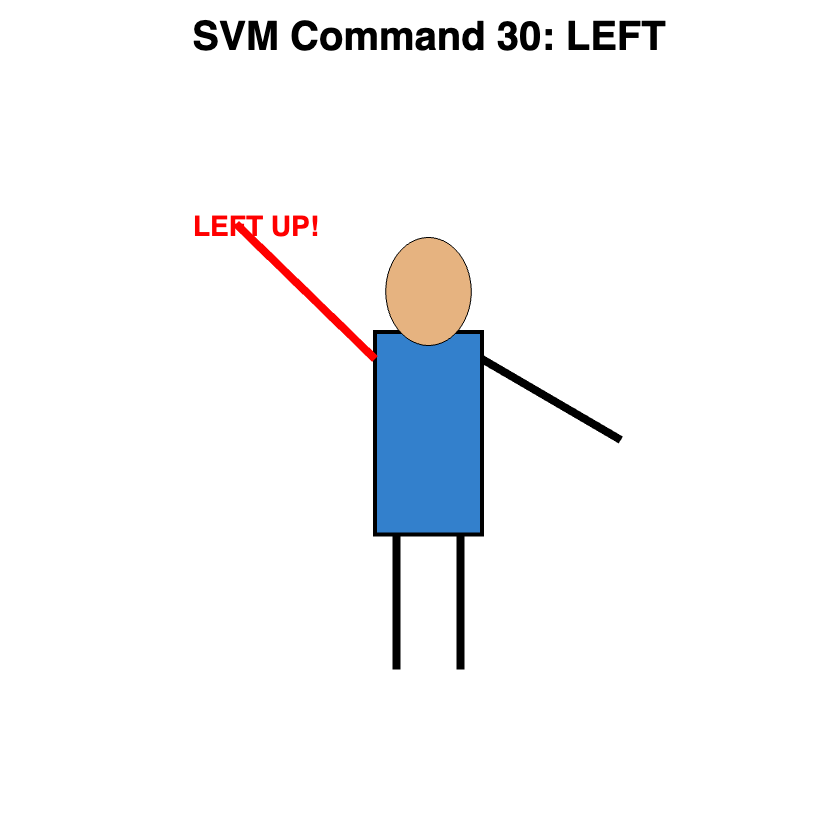


% Animate only first few commands so it does not run too long
numCommands = min(30, length(commands));

figure('Position', [100 100 600 600], 'Color', 'white');

for i = 1:numCommands
    cmd = commands{i};

    clf;

    % Draw robot based on SVM command
    draw_robot(cmd);

    % Show command and trial number
    title(['SVM Command ', num2str(i), ': ', cmd], ...
        'FontSize', 20, 'FontWeight', 'bold');

    drawnow;
    pause(1.5);
end


disp('SVM-based robot animation done!');

SVM-based robot animation done!



%% --- Robot drawing function ---


function draw_robot(command)
    hold on;
    axis([-3 3 -1 4]);
    axis off;

    % Body
    rectangle('Position', [-0.5 0.5 1 1.5], ...
        'FaceColor', [0.2 0.5 0.8], 'LineWidth', 2);

    % Head
    theta = linspace(0, 2*pi, 100);
    fill(0.4*cos(theta), 0.4*sin(theta)+2.3, [0.9 0.7 0.5]);

    % Legs
    line([-0.3 -0.3], [0.5 -0.5], 'Color', 'k', 'LineWidth', 4);
    line([0.3 0.3],   [0.5 -0.5], 'Color', 'k', 'LineWidth', 4);

    % Arms based on SVM command
    if strcmp(command, 'LEFT')
        % Left arm raised
        line([-0.5 -1.8], [1.8 2.8], 'Color', 'r', 'LineWidth', 4);
        line([0.5 1.8],   [1.8 1.2], 'Color', 'k', 'LineWidth', 4);

        text(-2.2, 2.8, 'LEFT UP!', ...
            'Color', 'red', 'FontSize', 14, 'FontWeight', 'bold');

    elseif strcmp(command, 'RIGHT')
        % Right arm raised
        line([-0.5 -1.8], [1.8 1.2], 'Color', 'k', 'LineWidth', 4);
        line([0.5 1.8],   [1.8 2.8], 'Color', 'r', 'LineWidth', 4);

        text(1.4, 2.8, 'RIGHT UP!', ...
            'Color', 'red', 'FontSize', 14, 'FontWeight', 'bold');

    else
        % REST — both arms down
        line([-0.5 -1.8], [1.8 1.2], 'Color', 'k', 'LineWidth', 4);
        line([0.5 1.8],   [1.8 1.2], 'Color', 'k', 'LineWidth', 4);

        text(-0.45, 3.1, 'REST', ...
            'Color', 'black', 'FontSize', 14, 'FontWeight', 'bold');
    end

    hold off;
end